% Initial setup
b = 0.2;
J = 0.1;
K = 0.02;
L = 0.4;
R = 2;
u = 1;
[num,den] = linmod('DCMotor');
P=tf(num,den);

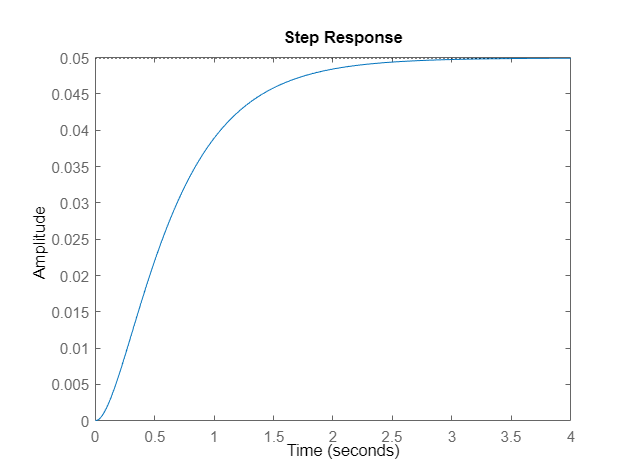

% Initial open loop graphs
figure(1);
step(u*P);

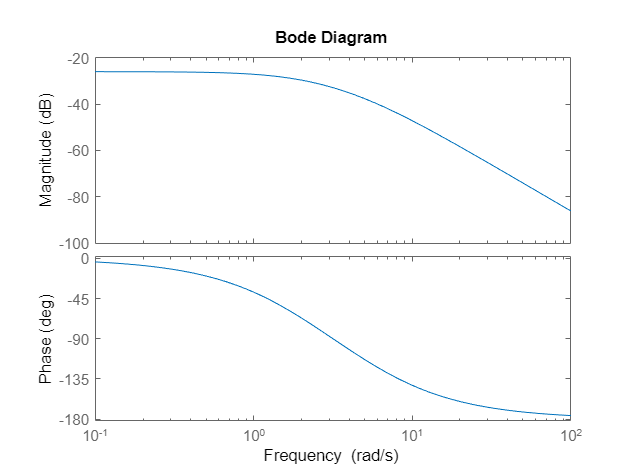

figure(2);
bode(P);

DC Motor Output with Low pass filter

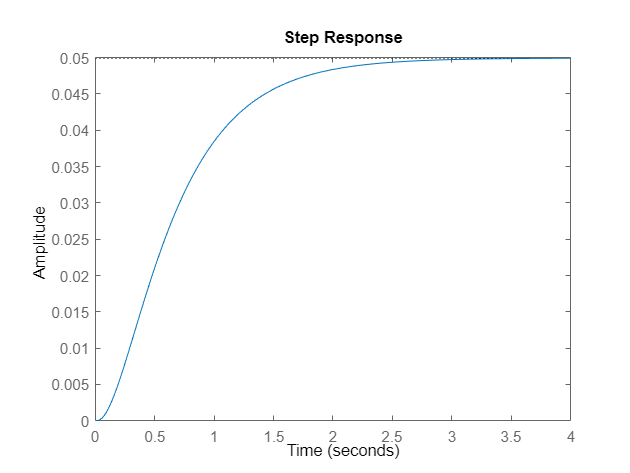

[num,den] = linmod('DCMotor1a');
P=tf(num,den);
figure(1);
step(u*P);

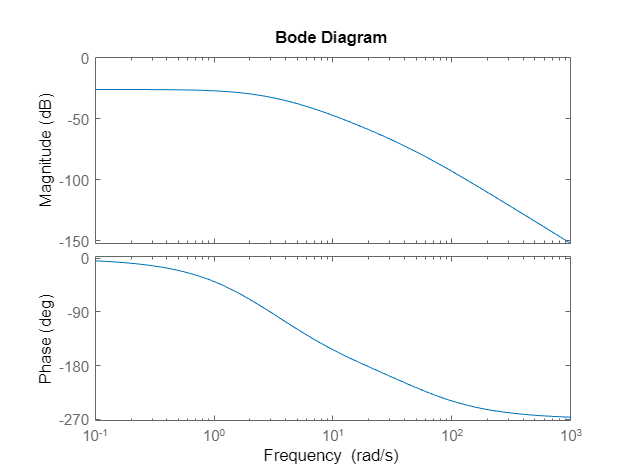

figure(2);
bode(P)

## Butterworth filter design:

%% Butterworth filter design:
% wc -passband cut-off frequency (rad/s)
% Rc -attenuation at passband cut-off (dB) (Rc > 0)
% ws -stopband frequency (rad/s)
% Rs -attenuation at stopband (dB) (Rs > 0)
wc=50;
Rc=3;
ws=70;
Rs=6;
epsilon = sqrt(10^(Rc/10)-1);
lambda = sqrt(10^(Rs/10)-1);
N_Bw = ceil(log(lambda/epsilon)/log(ws/wc));
disp(N_Bw);

     2



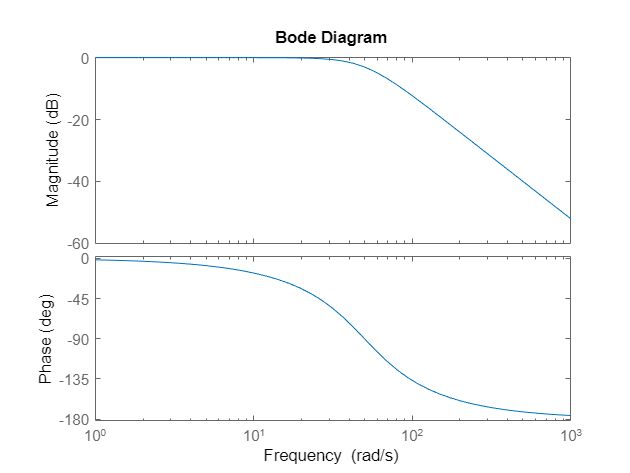

[numB,denB] = butter(N_Bw,wc,'s');
H = tf(numB,denB);
p_Bw=pole(H);
bode(H); % Bode plot

disp(p_Bw);

 -35.3553 +35.3553i
 -35.3553 -35.3553i



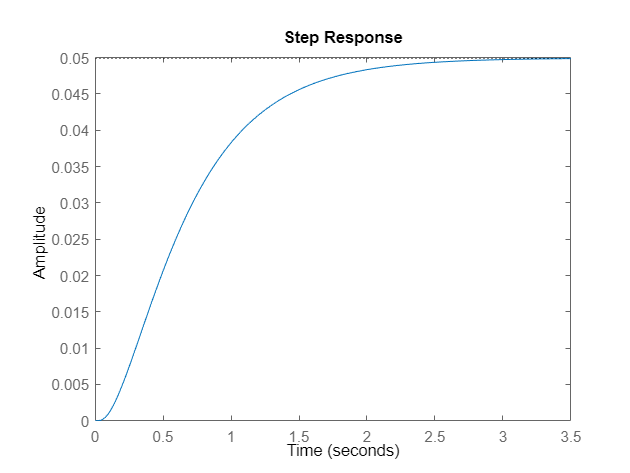

[num,den] = linmod('DCMotor1b');
P=tf(num,den);
figure(1);
step(u*P);

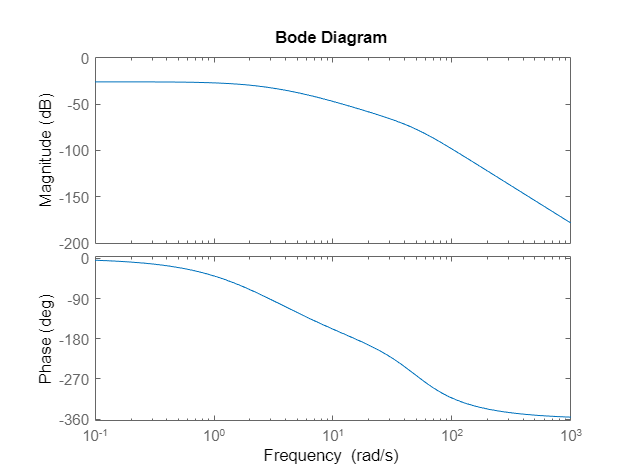

figure(2);
bode(P)

%ws=60
N_Bw = ceil(log(lambda/epsilon)/log(ws/wc));
disp(N_Bw);

     2



Chebyshev

%% Chebyshev Type 1 filter design:
% wc -passband cut-off frequency (rad/s)
% Rc -attenuation at passband cut-off (dB) (Rc > 0)
% ws -stopband frequency (rad/s)
% Rs -attenuation at stopband (dB) (Rs > 0).
% Rp -peak-to-peak ripple in the passband (dB) (Rp > 0).
close all;clc;
wc=50;
Rc=3;
ws=70;
Rs=6;
Rp=3;
epsilon = sqrt(10^(Rc/10)-1);
lambda = sqrt(10^(Rs/10)-1);
N_Cb1 = ceil(acosh(lambda/epsilon)/acosh(ws/wc));
disp(N_Cb1);

     2



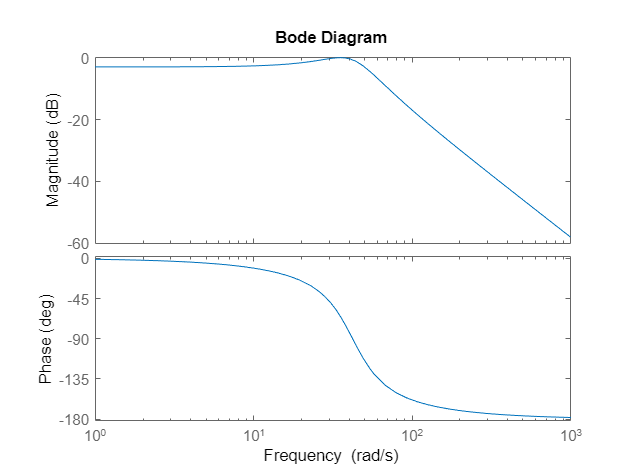

[numC1,denC1] =cheby1(N_Cb1,Rp,wc,'s');
H1 = tf(numC1,denC1);
p_Cb1=pole(H1);
bode(H1); % Bode plot

disp(p_Cb1);

 -16.1225 +38.8579i
 -16.1225 -38.8579i



Get response from the 1 file

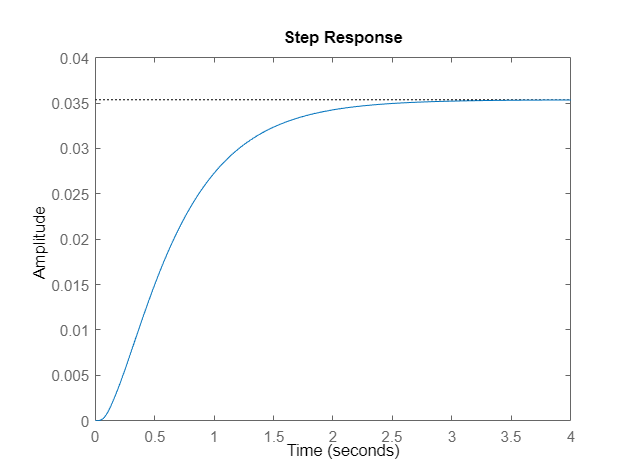

[num,den] = linmod('DCMotor1c');
P=tf(num,den);
figure(1);
step(u*P);

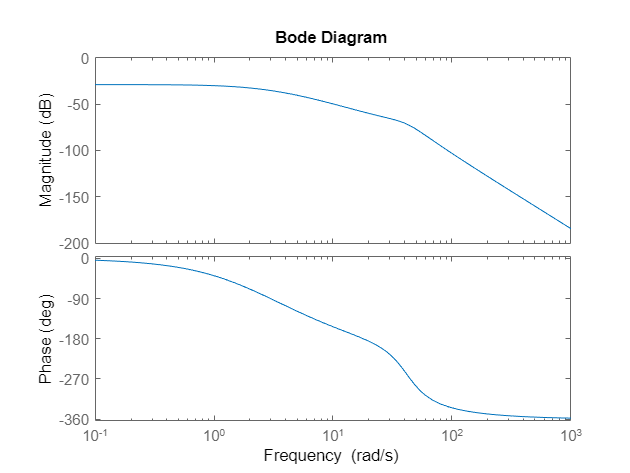

figure(2);
bode(P)

ws = 70;
wc= 50;
N_Cb1 = ceil(acosh(lambda/epsilon)/acosh(ws/wc));
disp(N_Cb1);

     2



Closed loop control

[num,den] = linmod('DCMotor1b');
P=tf(num,den);
zpk(P)

ans =
 
                        
                    1250
                        
  -----------------------------------------
                                           
  (s+4.997) (s+2.003) (s^2 + 70.71s + 2500)
                                           
                                           
 
Continuous-time zero/pole/gain model.



Kp = 100;
Ki = 150;
Kd = 10;
C = pid(Kp,Ki,Kd)

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 100, Ki = 150, Kd = 10
 
Continuous-time PID controller in parallel form.



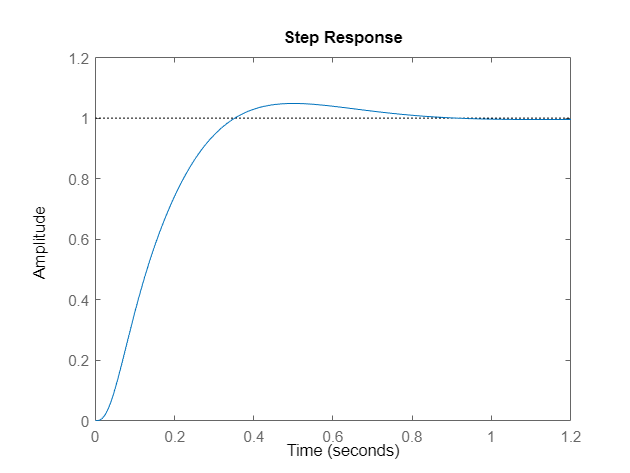

T = feedback(C*P,1);
step(T);